clc
clear all
close all

interpolation and decimation

ts = 60

ts = 60

x1 = 60:60: 360

x1 =     60   120   180   240   300   360


y= sind(x1)

y =     0.8660    0.8660         0   -0.8660   -0.8660         0


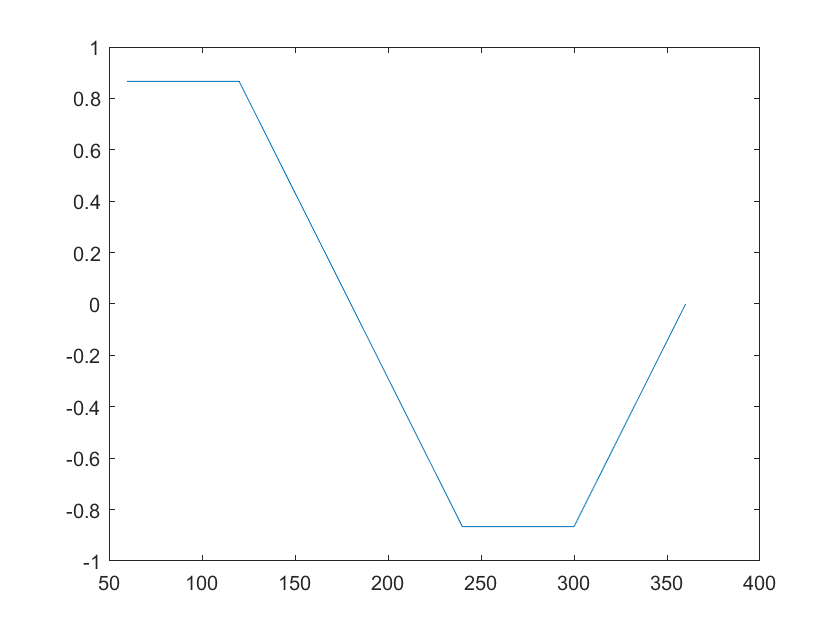

plot(x1,y)

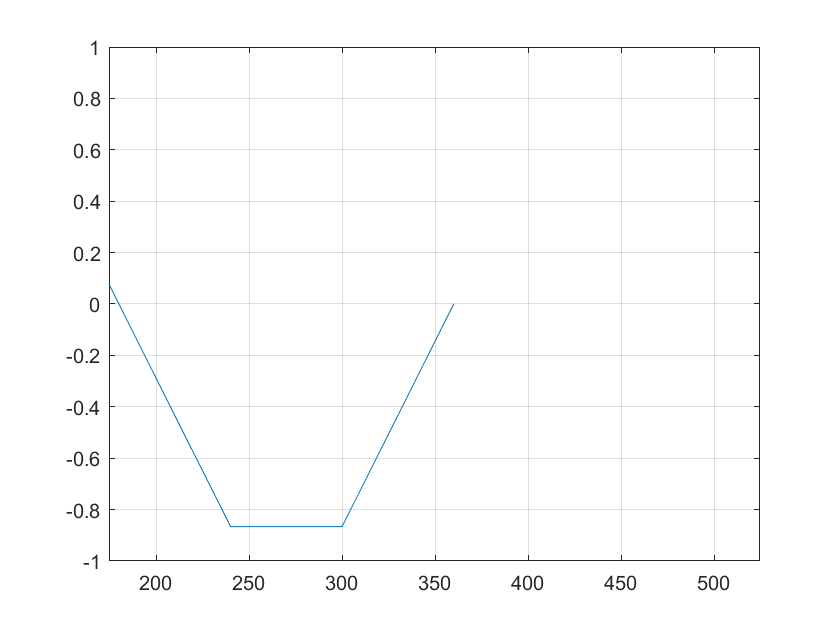

grid on

x2 = ts/4: ts/4 : 360

x2 =     15    30    45    60    75    90   105   120   135   150   165   180   195   210   225   240   255   270   285   300   315   330   345   360


y2 = interp1(x1, y, x2) % linear

y2 =        NaN       NaN       NaN    0.8660    0.8660    0.8660    0.8660    0.8660    0.6495    0.4330    0.2165         0   -0.2165   -0.4330   -0.6495   -0.8660   -0.8660   -0.8660   -0.8660   -0.8660   -0.6495   -0.4330   -0.2165         0


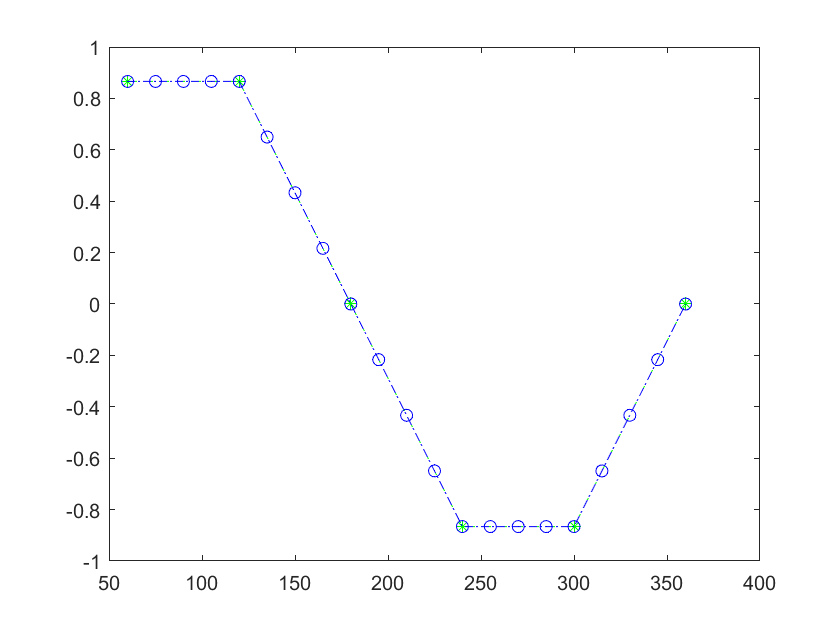

plot(x1,y,'g--*',x2,y2, 'b-.o')

x3 = ts/4: ts/4 : 360

x3 =     15    30    45    60    75    90   105   120   135   150   165   180   195   210   225   240   255   270   285   300   315   330   345   360


y3 = interp1(x1, y, x3, 'spline') % spline

y3 =    -0.1885    0.2887    0.6360    0.8660    0.9914    1.0248    0.9788    0.8660    0.6991    0.4907    0.2535         0   -0.2562   -0.4980   -0.7073   -0.8660   -0.9598   -0.9887   -0.9562   -0.8660   -0.7217   -0.5268   -0.2851         0


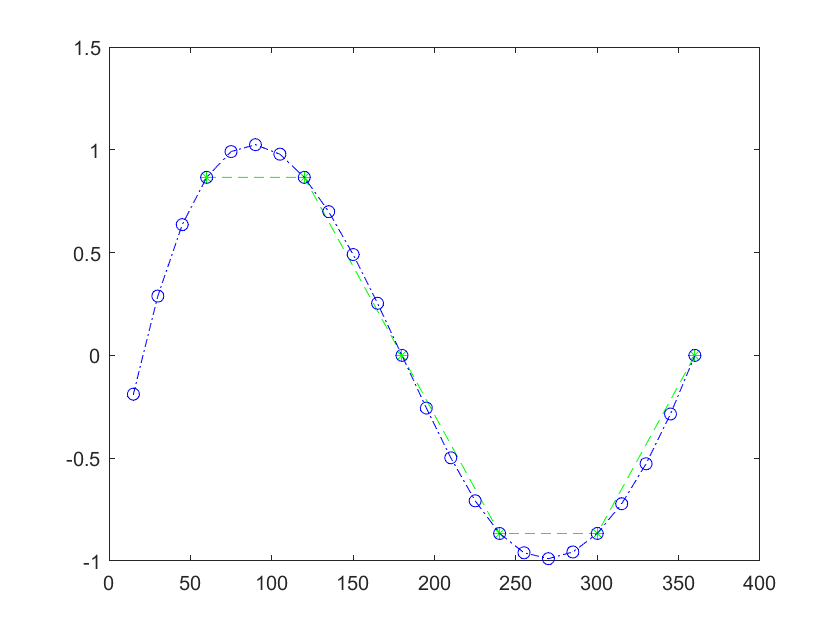

plot(x1,y,'g--*',x3,y3, 'b-.o')